***Exercise M-2.2***

clc;
clear;
% Define symbolic variable s
syms s;
G(s) = 1/(500*s^2); % Define G(s)
H(s) = (s+1)/(s+2); % Define H(s)
M(s) = simplify(G(s)/(1-G(s)*H(s))) % Define M(s) using the formula

$$M(s) = -\frac{s+2}{-500\,s^{3}-1000\,s^{2}+s+1}$$

***Exercise M-2.3***

clear;
clc;
syms s K;
G(s) = K / (s*(s+1)*(s^2+2*s+5));
G_partialfrac = partfrac(G(s))

$$G\_partialfrac = \frac{K}{5\,s}-\frac{K}{4\,\left(s+1\right)}-\frac{\frac{3\,K}{20}-\frac{K\,s}{20}}{s^{2}+2\,s+5}$$

G_partialfraction = subs(G_partialfrac,K,5)

$$G\_partialfraction = \frac{1}{s}-\frac{5}{4\,\left(s+1\right)}+\frac{\frac{s}{4}-\frac{3}{4}}{s^{2}+2\,s+5}$$

nominator = [5];denominator =[1 3 7 5 0];
[zeros,pole,direct_term] = residue(nominator,denominator)

zeros =    0.1250 + 0.2500i
   0.1250 - 0.2500i
  -1.2500 + 0.0000i
   1.0000 + 0.0000i


pole =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i
  -1.0000 + 0.0000i
   0.0000 + 0.0000i



direct_term =

     []



***Exercise M-2.4***

clear;
clc;
syms s;
Y(s) = (2*s^2+3*s+1)/(s^2+4*s+3);
denominator = [1 4 3];
nominator = [2 3 1];
[zeros,pole] = residue(nominator,denominator);
disp(zeros); % where Y(s) = 0

    -5
     0



disp(pole); % where Y(s) = infinity

    -3
    -1



***Exercise M-2.5***

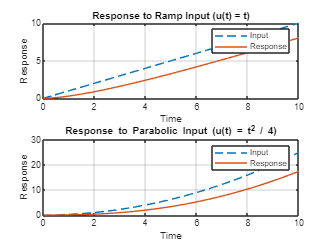

clc;
clear;
% G(s) = (s+1)/(s^2+3s+1)
num = [1 1];
den = [1 3 1];
G = tf(num,den);
t = 0:0.01:10;
ramp_input = t;
parabolic_input = t.^2/4;
ramp_response = lsim(G,ramp_input,t);
parabolic_response = lsim(G,parabolic_input,t);

figure;
subplot(2,1,1);
plot(t,ramp_input,'--');
grid on;
hold on;
plot(t,ramp_response);
xlabel('Time');
ylabel('Response');
title('Response to Ramp Input (u(t) = t)');
legend('Input','Response');
subplot(2,1,2);
plot(t,parabolic_input,'--');
hold on;
grid on;
plot(t,parabolic_response);
xlabel('Time');
ylabel('Response');
title('Response to Parabolic Input (u(t) = t^2 / 4)');
legend('Input','Response');

***Exercise M-2.6***

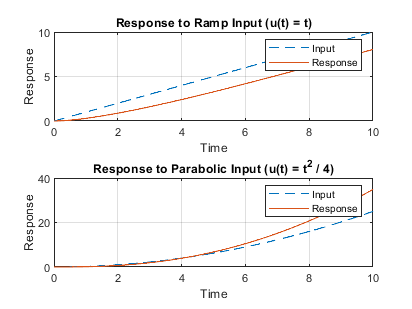

clc;
clear;
% G(s) = (s+1)/(s^2+3s+1)
num = [1 1];
den = [1 3 1];
G = tf(num,den);
ramp_input = tf(num, conv(den, [1 0])); % G(s)/s
parabolic_input = tf(num, conv(den, [1 0 0])); % G(s)/s^2
t = 0:0.01:10;
ramp_response = step(ramp_input,t);
parabolic_response = step(parabolic_input,t);
figure;
subplot(2,1,1);
plot(t,t,'--');
grid on;
hold on;
plot(t,ramp_response);
xlabel('Time');
ylabel('Response');
title('Response to Ramp Input (u(t) = t)');
legend('Input','Response');
subplot(2,1,2);
plot(t,t.^2/4,'--');
hold on;
grid on;
plot(t,parabolic_response);
xlabel('Time');
ylabel('Response');
title('Response to Parabolic Input (u(t) = t^2 / 4)');
legend('Input','Response');

***Exercise M-2.7***

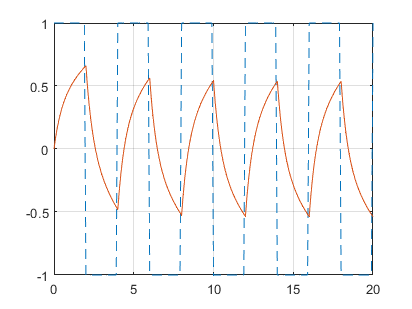

clc;
clear;
num = [1 1]; % Numerator coefficients
den = [1 3 1]; % Denominator coefficients
G = tf(num, den); % Transfer function
t = 0:0.1:20;
period = 4;
square_input = square(2*pi*t/period);
square_response = lsim(G,square_input,t);
figure;
plot(t,square_input,'--');
hold on;
plot(t,square_response);
grid on;

***Exercise M-2.8***

clc;
clear;
syms s K A T;
G(s) = (A/s) * (K/(T*s + 1));
pretty(G(s))

    A K
-----------
s (T s + 1)



ilaplace(G(s))

$$ans = A\,K-A\,K\,{\mathrm{e}}^{-\frac{t}{T}}$$

***Exercise M-2.9***

clc;
clear;
syms t s;
g(t) = 1+(1/3)*exp(-4*t)-(4/3)*exp(-t);
G(s) = laplace(g(t))

$$G(s) = \frac{1}{3\,\left(s+4\right)}-\frac{4}{3\,\left(s+1\right)}+\frac{1}{s}$$

***Exercise M-2.10***

clc;
clear;
syms s a b t;
g(t) = 1+(b/(a-b))*exp(-a*t)-(a/(a-b))*exp(-b*t);
G(s) = laplace(g(t))

$$G(s) = \frac{1}{s}-\frac{a}{\left(b+s\right)\,\left(a-b\right)}+\frac{b}{\left(a+s\right)\,\left(a-b\right)}$$

simplify(G(s))

$$ans = \frac{a\,b}{s\,\left(a+s\right)\,\left(b+s\right)}$$